# Time-dependent variational principle (TDVP): 1-site variant

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we will implement the 1-site TDVP method for simulating the real-time evolution of one-dimensional quantum states.

## Exercise (a): Complete the function for 1-site TDVP

There is a function `TDVP_1site_Ex.m`, which is in the same sub-directory with this script. It is incomplete. This function is designed to perform the real-time evolution of the MPS via the 1-site TDVP method, and to measure the expectation values of a local operator (given as input) at every site after every time step.

The detailed algorithm is described in described in Appendix B of Haegeman2016 [[J. Haegeman, C. Lubich, I. Oseledets, B. Vandereycken, and F. Verstraete, Phys. Rev. B **94**, 165116 (2016)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.94.165116)] or Sec. 6.2 of Paeckel2019 [[S. Paeckel, T. Köhler, A. Swoboda, S. R. Manmana, U. Schollwöck, and C. Hubig, Ann. Phys. **411**, 167998 (2019)](https://www.sciencedirect.com/science/article/pii/S0003491619302532?via%3Dihub)].

As described in those papers, the 1-site TDVP algorithm is quite similar to the 1-site DMRG for ground-state search. Accordingly, the TDVP takes the Hamiltonian in its MPO form. So one may recycle the DMRG code, `DMRG/DMRG_GS_1site.m`. `TDVP_1site_Ex.m` contains subfunctions `TDVP_1site_expHA` and `TDVP_1site_expHC` for the Lanczos method for local time evolutions. Complete these subfunctions as well, by adapting from the Lanczos subfunctions of `DMRG/DMRG_GS_1site.m`.

After completing the `TDVP_1site_Ex.m`, you can consider the following example of the XY chain, discussed in the previous tutorial on tDMRG.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

% TDVP parameters
Nkeep = 20; % bond dimension
dt = 1/20; % discrete time step size
tmax = 15; % maximum time

% operator to measure magnetization
Sz = S(:,:,2);

As in the tDMRG tutorial, we consider a direct product state as the initial state at time $t = 0$, whose left (right) half is up-polarized (down-polarized):


$$| \Psi (t = 0) \rangle = |\!{\uparrow} \rangle_1 |\!{\uparrow} \rangle_2 \cdots |\!{\uparrow} \rangle_{L/2-1} |\!{\uparrow} \rangle_{L/2} |\!{\downarrow} \rangle_{L/2+1} |\!{\downarrow} \rangle_{L/2+2} \cdots |\!{\downarrow} \rangle_{L-1} |\!{\downarrow} \rangle_{L} .$$


In the tDMRG tutorial, the MPS for the initial state had singleton bond dimensions, since it's separable (i.e., not entangled).

However, there is a crucial difference in this 1-site TDVP tutorial. Since 1-site update methods cannot increase bond dimensions, we need to declare large tensors, mostly filled with zeros, in the beginning. (The tDMRG method we implemented is, indeed, a 2-site update method!)

M = cell(1,L);
v = [1,1e-8]; v = v/norm(v);
for itN = (1:L)
    if itN == 1
        M{itN} = zeros(1,Nkeep,size(I,2));
    elseif itN == L
        M{itN} = zeros(Nkeep,1,size(I,2));
    else
        M{itN} = zeros(Nkeep,Nkeep,size(I,2));
    end

    if itN <= (L/2)
        M{itN}(1,1,:) = reshape(v,[1 1 2]);
    else
        M{itN}(1,1,:) = reshape(fliplr(v),[1 1 2]);
    end
end

Here we assigned very small but finite coefficients to the spin-down (spin-up) basis states for the left (right) half, though in the tDMRG demonstration they were true zeros. Such treatment here is to stabilize the numerics.

Before starting "sweeps" upating tensors, the initial MPS is brought into a canonical form, which involves a series of thin SVDs. In the thin SVD of a non-square matrix, there can be a problem if the number of "finite" singular values is smaller than the smaller dimension of the matrix. (Here "finite" means values that are not true zeros. So numerical precision noise is also regarded "finite" in this argument.) In such a case, the singular vectors associated with truly vanishing singular values are chosen arbitrarily from the null space, and such chosen singular vectors can be physically irrelevant. By setting small numbers instead of true zeros, this problem can be suppressed.

Those small numbers to not increase the error of the calculation results, since the other error sources dominate. Also, this issue can be avoided if we use the 2-site TDVP, since 2-site updates can automatically choose relevant subspaces.

Let's run the TDVP calculation.

[ts,M,Ovals,EE] = TDVP_1site_Ex (M,Hs,Sz,Nkeep,dt,tmax);

TDVP : Real-time evolution with local measurements
N = 40, Nkeep = 20, dt = 0.05, tmax = 15 (300 steps)
22-10-30 23:51:30 | Time evolution: start.
22-10-30 23:51:49 | #30/300 : t = 1.5/15
22-10-30 23:52:07 | #60/300 : t = 3/15
22-10-30 23:52:27 | #90/300 : t = 4.5/15
22-10-30 23:52:47 | #120/300 : t = 6/15
22-10-30 23:53:06 | #150/300 : t = 7.5/15
22-10-30 23:53:24 | #180/300 : t = 9/15
22-10-30 23:53:41 | #210/300 : t = 10.5/15
22-10-30 23:53:59 | #240/300 : t = 12/15
22-10-30 23:54:17 | #270/300 : t = 13.5/15
22-10-30 23:54:36 | #300/300 : t = 15/15
Elapsed time: 185.9s, CPU time: 1628s, Avg # of cores: 8.758
22-10-30 23:54:36 | Memory usage : 2.72GiB


We plot the magnetization and its error, by comparing with the exact result.

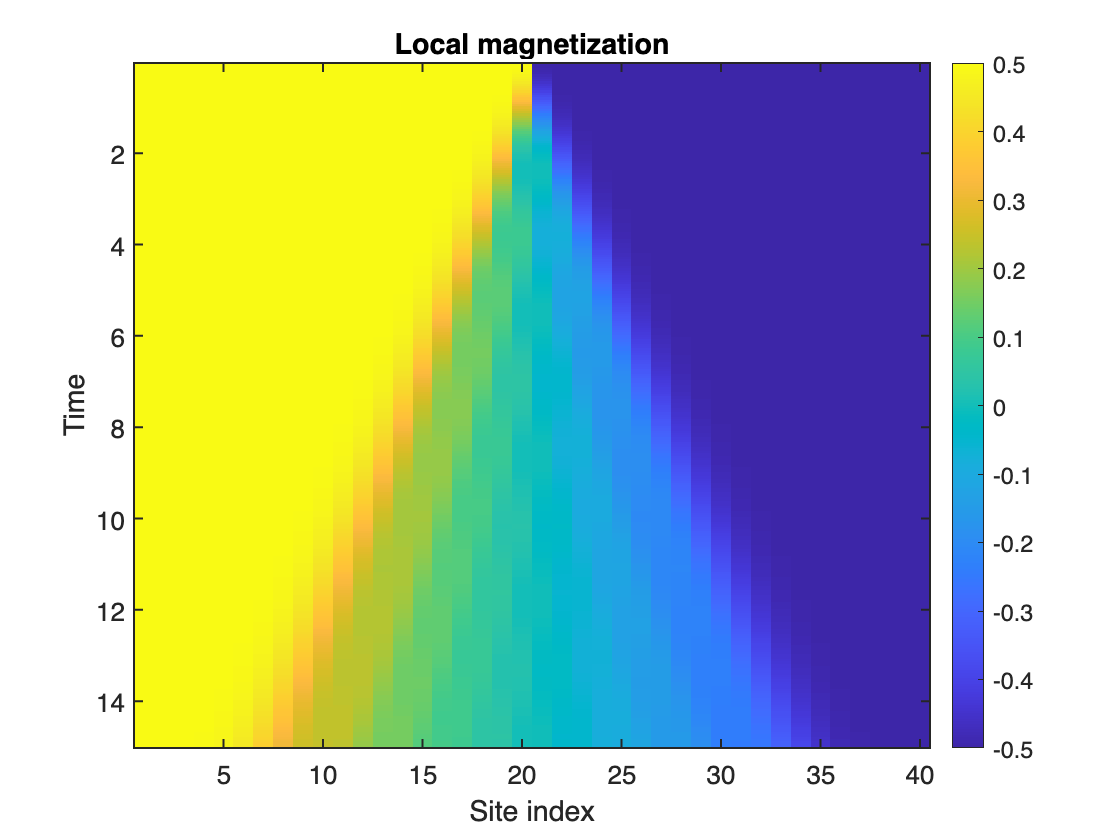

figure;
imagesc([1 L],[ts(1) ts(end)],real(Ovals));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Local magnetization');

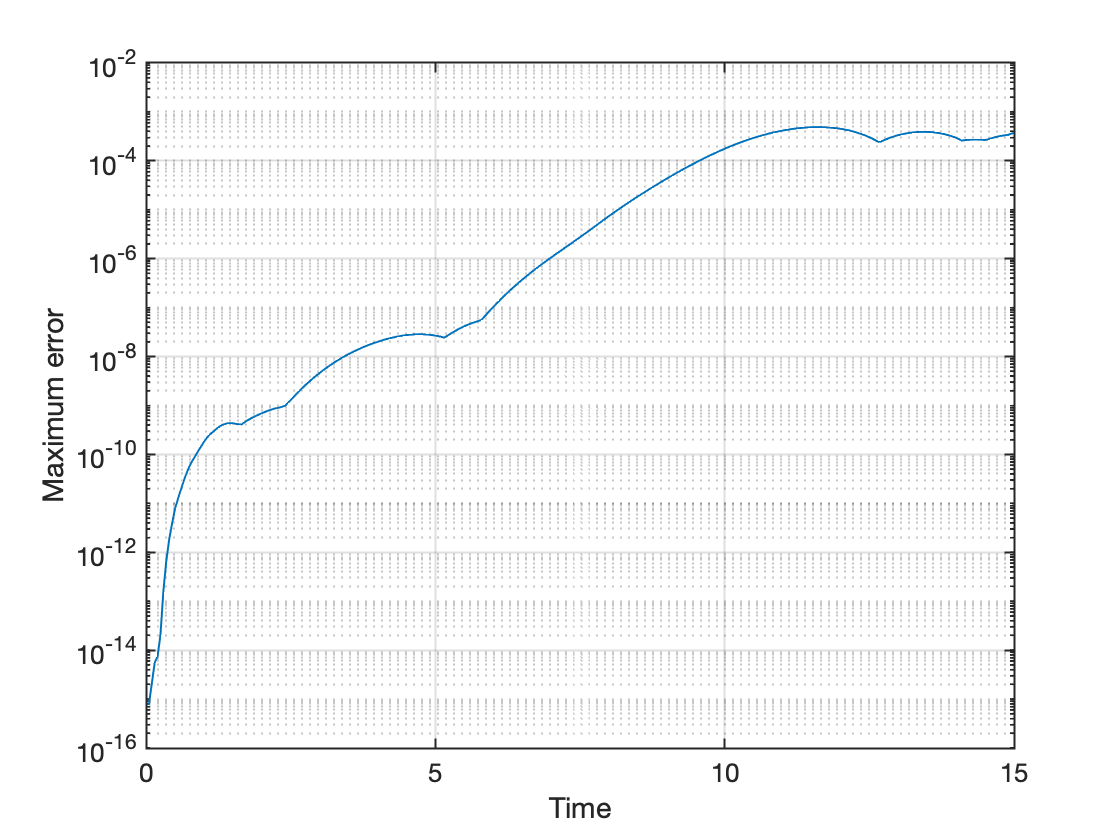

% exact values of magnetization in the infinite chain limit
fvals = zeros(numel(ts),L-1);
for it = (1:size(fvals,2))
    % Bessel function of the 1st kind
    fvals(:,it) = (besselj(it-(L/2),ts(:))).^2;
end
fvals = -0.5*fvals;

Oexact = zeros(numel(ts),L/2); % exact values
for it = (1:(L/2))
    Oexact(:,it) = sum(fvals(:,(L/2-it+1):(it+L/2-1)),2);
end
Oexact = [-fliplr(Oexact),Oexact];

% error between numerical and exact results
figure;
% maximum error along the chain at each time instance
plot(ts,max(abs(Ovals-Oexact),[],2),'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1,'YScale','log');
grid on;
xlabel('Time');
ylabel('Maximum error');

## Exercise (b): Compare the accuracy between 1-site TDVP and tDMRG

Analyze how the error depends on the parameters `Nkeep` and `dt`. Compare the errors from TDVP calculations with those from tDMRG with the same parameters.